%% Clearing all the output
clc;
close all;
%% The constant values are imported in the workspace_data file as defined in the problem
%Defining the matrices as follows
A=[0 1 0 0 0 0; 
    0 0 -(m_1*g)/M 0 -(m_2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m_1)*g)/(M*l_1) 0 -(m_2*g)/(M*l_1) 0;
    0 0 0 0 0 1;
    0 0 -(m_1*g)/(M*l_2) 0 -(g*(M+m_2))/(M*l_2) 0];
B=[0; 1/M; 0; 1/(M*l_1); 0; 1/(M*l_2)];
% From the previous calculations, we know that only C1, C3 and C4 were
% observable. Hence, we are considering only those 3 cases here below.

C_1_matrix = [1 0 0 0 0 0];  %Matrix corresponding to x-component
C_3_matrix = [1 0 0 0 0 0; 0 0 0 0 1 0]; %Matrix corresponding to x and theta2
C_4_matrix = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 0 1 0]; %Matrix corresponding to x, theta1 and theta2
D_matrix = 0;%declaring the D matrix to be zero
% Cosidering the same Q and R matrices chosen before in our code
Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.01; %%these are the variables used in cost function from LQR
% The initial conditions for Leunberger observer consists of 12 state variables are as follows,
% where we are considering 6 actual and 6 estimates
x0=[0,0,30,0,60,0,0,0,0,0,0,0];
% The order of state variables is as follows = [x,dx,theta_1,dtheta_1,theta_2,dtheta_2, 
% estimated_x,estimated_dx,estimated_theta_1,estimated_dtheta_1,estimated_theta_2,estimated_dtheta_2]

% For pole placement, we will choose eigen values with negative real part for stability
poles=[-1;-2;-3;-4;-5;-6];
% Calling LQR function to obtain K matrix
K=lqr(A,B,Q,R);
% Framing L for all three cases where output is observable
% Using the pole placement funciton built into MATLAB
L_1 = place(A',C_1_matrix',poles)' %L_1 should be a 6x1 matrix

L_1 = 1.0e+03 *

    0.0210
    0.1734
   -2.9262
    0.0805
    2.2116
   -1.4493


L_3 = place(A',C_3_matrix',poles)' %L_3 should be a 6x2 matrix

L_3 =    13.0744   -0.8244
   56.2562   -8.4805
  -89.0764   19.7693
  -20.0115   10.9419
    0.3520    7.9256
    3.4793   13.2122


L_4 = place(A',C_4_matrix',poles)' %L_4 should be a 6x3 matrix

L_4 =     8.5631   -0.8851    0.0000
   17.5219   -4.9484   -0.9810
   -0.9140    9.4369   -0.0000
   -4.1173   20.9385   -0.0491
    0.0000   -0.0000    3.0000
    0.0000   -0.0981    0.9209


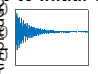


A_c1 = [(A-B*K) B*K; % Luenberger A matrix
        zeros(size(A)) (A-L_1*C_1_matrix)];
B_c = [B;zeros(size(B))];% Luenberger B matrix
C_c1 = [C_1_matrix zeros(size(C_1_matrix))];% Luenberger C matrix

A_c3 = [(A-B*K) B*K;% Luenberger A matrix
        zeros(size(A)) (A-L_3*C_3_matrix)];
C_c3 = [C_3_matrix zeros(size(C_3_matrix))];% Luenberger C matrix

A_c4 = [(A-B*K) B*K;% Luenberger A matrix
        zeros(size(A)) (A-L_4*C_4_matrix)];
C_c4 = [C_4_matrix zeros(size(C_4_matrix))];% Luenberger C matrix

system_1 = ss(A_c1, B_c, C_c1,D_matrix);%Inbuilt MATLAB function to output the state space equations
figure % launching a new figure WINDOW in Matlab
initial(system_1,x0)%Inbuilt MATLAB function to verify the initial response  of the system

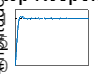

figure
step(system_1)%Provides the step output response of the system

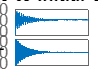


system_3 = ss(A_c3, B_c, C_c3,D_matrix);%Inbuilt MATLAB function to output the state space equations
figure % launching a new figure WINDOW in Matlab
initial(system_3,x0)%Inbuilt MATLAB function to verify the initial response  of the system

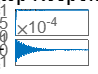

figure 
step(system_3)%Provides the step output response of the system

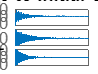


system_4 = ss(A_c4, B_c, C_c4, D_matrix);%Inbuilt MATLAB function to output the state space equations
figure % launching a new figure WINDOW in Matlab
initial(system_4,x0)%Inbuilt MATLAB function to verify the initial response  of the system

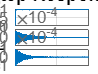

figure 
step(system_4)%Provides the step output response of the system

grid on